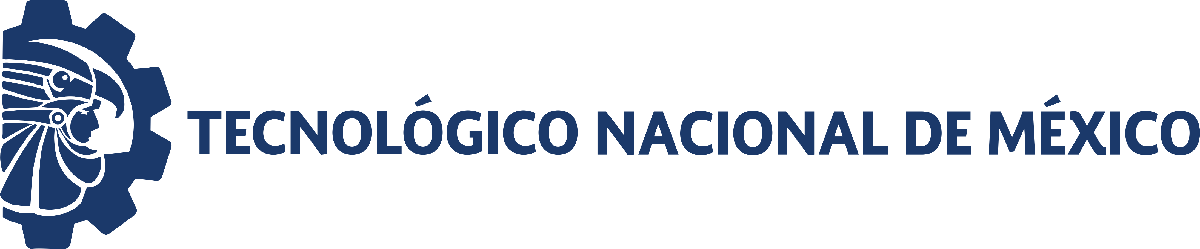                                 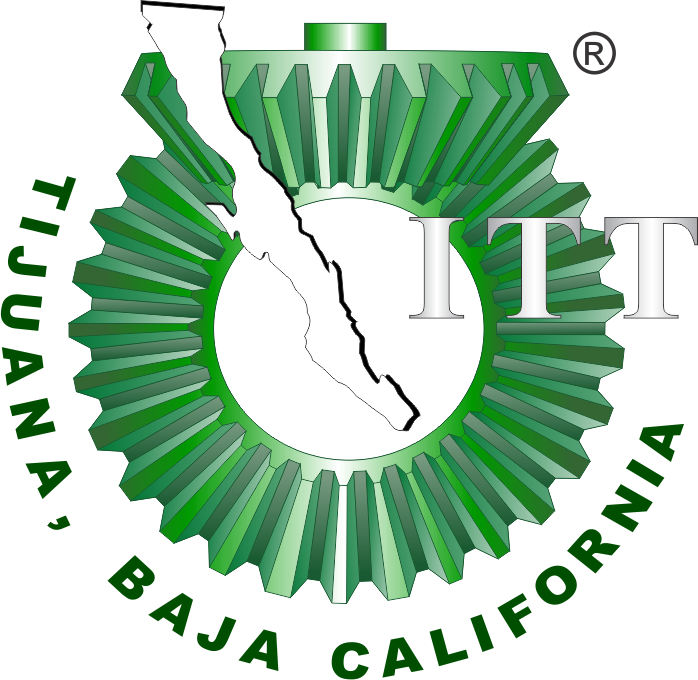

# Práctica tres: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

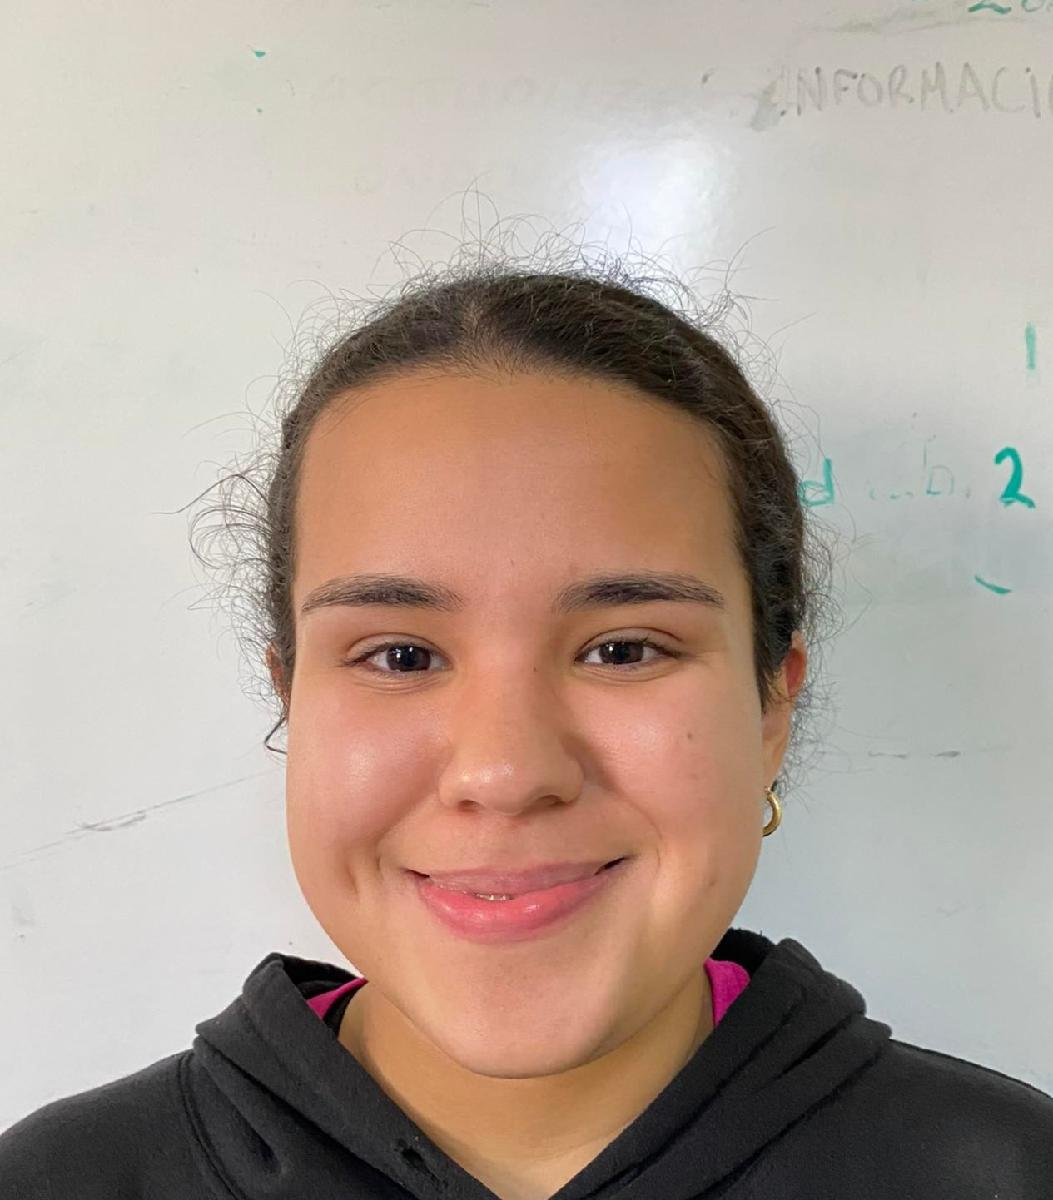

Nombre del alumno: **Mariana Rivera Peñuelas** 

Número de control: **22210427**

Correo institucional: **l22210427@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
parameters.StopTime = tend;
parameters.Solver = 'ode15s';

## Respuesta a las tres funciones

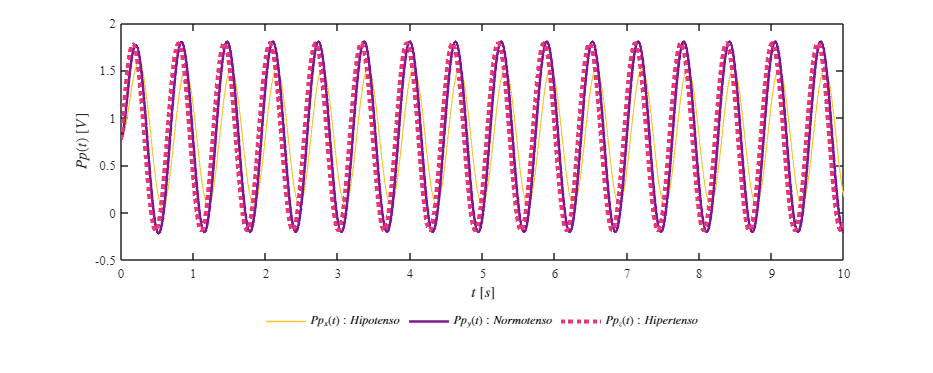

Signal = 'Sistema_cardiovascular';
file = 'sysP3';
open_system(file);
N = sim(file, parameters);
opt = 1;
plotsignals(N.t, N.Ppx, N.Ppy, N.Ppz, opt, Signal)

## Respuesta a la señal hipotenso

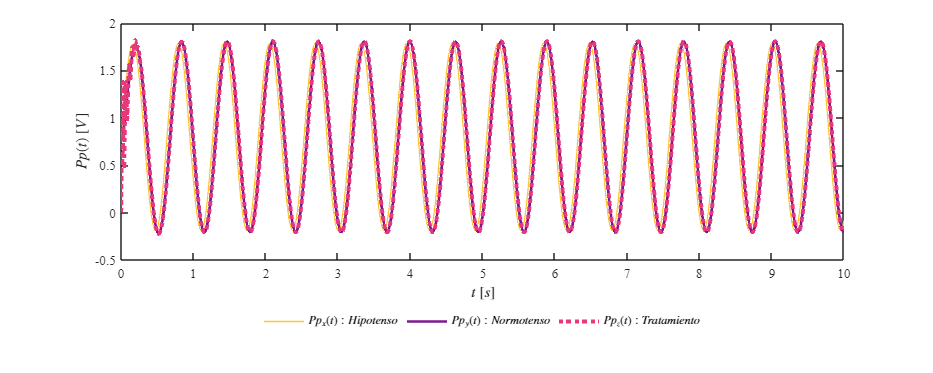

Signal = 'Hipotenso';
file = 'Rivera22210427HIPO';
open_system(file);
N = sim(file, parameters);
opt = 2;
plotsignals (N.t, N.Ppx, N.Ppy, N.Ppz, opt, Signal)

## Respuesta a la señal hipertenso

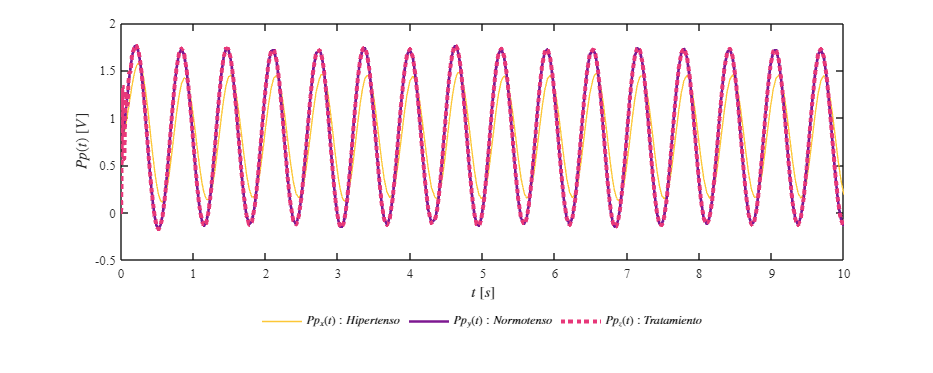

Signal = 'Hipertenso';
file = 'Rivera22210427HIPER';
open_system(file);
N = sim(file, parameters);
opt = 3;
plotsignals (N.t, N.Ppx, N.Ppy, N.Ppz, opt, Signal)

## Función: Respuestas a las señales

function plotsignals(t, Ppx, Ppy, Ppz, ~, Signal)
    set(figure(), 'Color', 'w')
    set(gcf, 'units', 'Centimeters', 'Position', [1,5,30,12])
    set(gca, 'FontName', 'Times New Roman')
    fontsize(10, 'points')
    AMARILLO = [252/255, 199/255, 55/255];
    MORADO = [126/255, 24/255, 145/255];
    ROSA = [231/255, 56/255, 121/255];
    hold on; grid off; box on
    plot(t,Ppx,'LineWidth',1, 'Color', AMARILLO)
    plot(t,Ppy,'LineWidth',2,'Color', MORADO)
    plot(t,Ppz,':','LineWidth',3,'Color', ROSA)
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex')
    ylabel('$Pp(t)$ $[V]$', 'Interpreter', 'Latex')
    
    if Signal == "Sistema_cardiovascular"
    L = legend('$Pp_{x}(t):Hipotenso$', '$Pp_{y}(t):Normotenso$', '$Pp_{z}(t):Hipertenso$');
    set(L, 'Interpreter', 'Latex', 'Location', 'southoutside','Orientation', 'horizontal', 'Box', 'Off')
    elseif Signal == "Hipotenso"
    L = legend('$Pp_{x}(t):Hipotenso$', '$Pp_{y}(t):Normotenso$', '$Pp_{z}(t):Tratamiento$');
    set(L, 'Interpreter', 'Latex', 'Location', 'southoutside','Orientation', 'horizontal', 'Box', 'Off')
    elseif Signal == "Hipertenso"
    L = legend('$Pp_{x}(t):Hipertenso$', '$Pp_{y}(t):Normotenso$', '$Pp_{z}(t):Tratamiento$');
    set(L, 'Interpreter', 'Latex', 'Location', 'southoutside','Orientation', 'horizontal', 'Box', 'Off')
    end
   exportgraphics(gcf,[Signal,'.pdf'],'ContentType','Vector')

end